# PREPROCESO


clear all
clf
close all



imageToMask = imread('C:\Users\User\Desktop\dataset\asl_alphabet_train\asl_alphabet_train\H\H2021.jpg');


maskImage = imread('C:\Users\User\Desktop\mask.jpg');
maskImage = bitcmp(maskImage);

threshold = 128; % Adjust as needed
binaryMask = maskImage > threshold;

% Create a copy of the original image to apply the mask
maskedImage = imageToMask;

% Apply the mask to the image
maskedImage(binaryMask) = 0; % Set masked pixels to black (0)

% Display the original image, mask image, and masked image





%%% Mejorando la imagen

img = imageToMask

img = 200×200×3 uint8 array
img(:,:,1) =

     0     0     5     8     6     1     2     1     4     2     0     0     0     1     4     4     4     2     1     1     1     1     0     0     0     0     1     1     2     2     4     2     1     1     1     1     1     1     1     1     0     1     1     1     1     1     2     2     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     1     1     1     1     0     0     0     0     0     1     0     0     1     2     1     1     0     0     0     0     0     0     1     1     1     1     0     1     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     1     1     2     2     4     4     2     2     1     1     0     0     0     0     0     0     0     1     2     2     4    

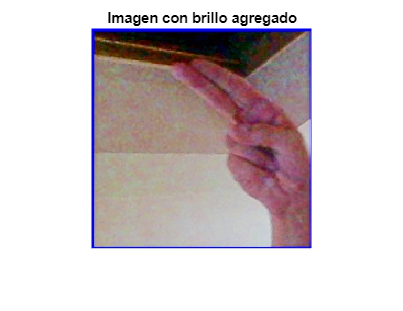

% ILUMINACION                   ilumina la imagen
    amt = 0.75;
    img = imlocalbrighten(img,amt,AlphaBlend=true);
    imshow(img);
    title('Imagen con brillo agregado');

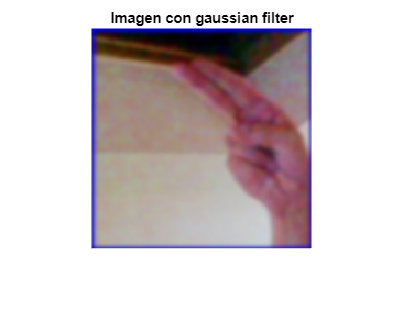

%%%%%%%%%%%%
% GAUSSIAN FILTER               ruido, smoth, brillo y granulado
   sigma = 2; % "level" of gaussian filter
   img = imgaussfilt(img, sigma);
   imshow(img);
   title('Imagen con gaussian filter');

%%%%%%%%%%%%%%




% MEDIAN FILTER                 smoth, brillo y granulado
    [height,width,numChannels] = size(img) % jsut in case

height = 200

width = 200

numChannels = 3

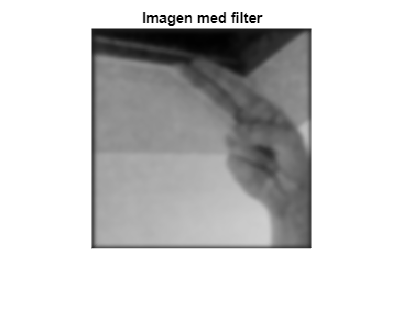

    if numChannels > 1
      grayImage = rgb2gray(img);
    else
       grayImage = img;
    end
   windowSize = [3, 3]; % Kernel
   img = medfilt2(grayImage, windowSize);
   imshow(img);
   title('Imagen med filter');

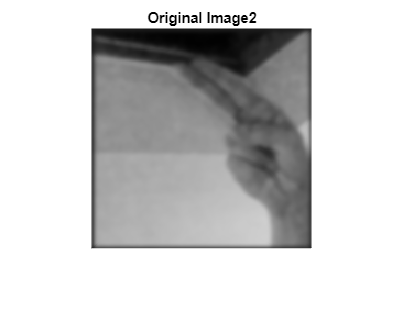

%%%%%%%%%%%%%%%%
% EQUALIZACION DE HISTOGRAMAS           para mejorar contraste

    


    imshow(img);
    title('Original Image2');

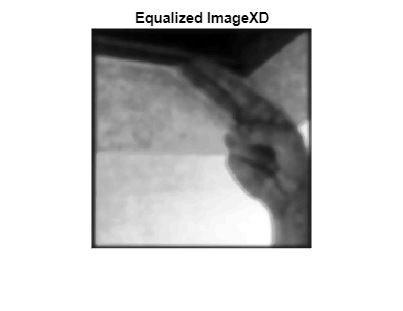


    img = histeq(img);

    imshow(img);
    title('Equalized ImageXD');

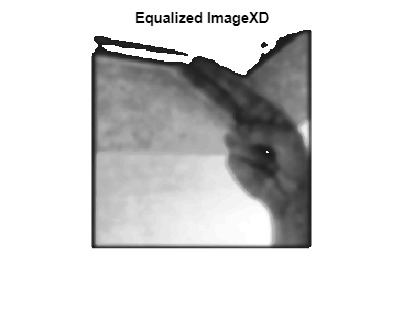

%%%%%%%%%%%%%%%%

% Check if a pixel is completely black (0) or close to it, convert it to white (255)
    img(img < 25) = 255;
    imshow(img);
    title('Equalized ImageXD');

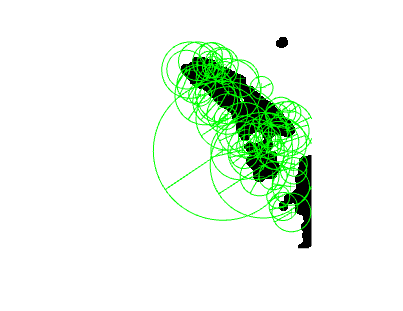

% ECUALIZADOR DE HISTOGRAMAS ADAPTATIVOS para mejorar contraste

    % img = adapthisteq(img,'clipLimit',0.2,'Distribution','rayleigh');
    % imshow(img);
    % title('Original ñ)')
%%%%%%%%%%%%%%%%

% TRESHOLD 
thresholdValue = 80; % Adjust this value as needed
img = img >= thresholdValue;
%%%%%%%%%%%%%%%%
% LAPLACIAN (SHARPENING)        sharpenea los edges
    % laplacianSharp = [0, -1, 0; -1, 5, -1; 0, -1, 0];
    % img = imfilter(img, laplacianSharp);
    % imshow(img);
    % title('Imagen con laplacian');
%%%%%%%%%%%%%




% ECUALIZADOR DE HISTOGRAMAS ADAPTATIVOS para mejorar contraste
    % if numChannels > 1
    %   grayImage = rgb2gray(img);
    % else
    %    grayImage = img;
    % end
    % J = adapthisteq(grayImage,'clipLimit',0.02,'Distribution','rayleigh');
    % imshowpair(grayImage,J,'montage');
    % title('Original Image (left) and Contrast Enhanced Image (right)')
%%%%%%%%%%%%%%%%

% Anisotropic Diffusion Filter: Anisotropic diffusion is used for edge-preserving
% smoothing. It can remove noise while preserving the edges in an image.
% ANTISOTROPIC DIFFUSION
% Define the number of iterations for anisotropic diffusion (e.g., 10)
    % numIterations = 10; 
    % filteredImage = imdiffusefilt(img, 'NumberOfIterations', numIterations);
    % 
    % imshow(filteredImage);
    % title('Filtered Image (Anisotropic Diffusion)');
%&%%%%%%%%%%%%%%

% Dilata la imagen
    % Kernel
    se = strel('disk', 5);

    % Perform dilation
    
    img = imdilate(img, se);
    img = imerode(img, se);
%%%%%%%%%%%%%%%%



points = detectSURFFeatures(img);

[features,valid_points] = extractFeatures(grayImage,points);

figure;
imshow(img);
hold on;
plot(valid_points.selectStrongest(50),showOrientation=true);

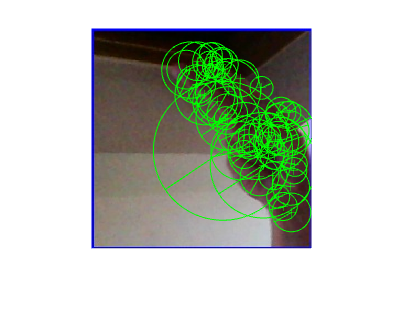


figure;
imshow(imageToMask);
hold on;
plot(valid_points.selectStrongest(50),showOrientation=true);

## BAG OF VISUAL WORDS

wea = 'C:\Users\User\Desktop\dataset\asl_alphabet_train\asl_alphabet_train'

wea = 'C:\Users\User\Desktop\dataset\asl_alphabet_train\asl_alphabet_train'

imds = imageDatastore(wea,'IncludeSubfolders',true,'LabelSource',...
    'foldernames');

addpath('C:\Program Files\MATLAB\R2023b\Myfunctions');

[trainingSet,testSet] = splitEachLabel(imds,0.3,'randomize');

extractor = @CustomSurf;
bag = bagOfFeatures(imds, 'CustomExtractor', extractor)

Creating Bag-Of-Features.
-------------------------
* Image category 1: A
* Image category 2: B
* Image category 3: C
* Image category 4: D
* Image category 5: G
* Image category 6: H
* Extracting features using a custom feature extraction function: CustomSurf.

* Extracting features from 17934 images...done. Extracted 1188734 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 5 has the least number of strongest features: 141706.
** Using the strongest 141706 features from each of the other image categories.

* Creating a 500 word visual vocabulary.
* Number of levels: 1
* Branching factor: 500
* Number of clustering steps: 1

* [Step 1/1] Clustering vocabulary level 1.
* Number of features          : 850236
* Number of clusters          : 500
* Initializing cluster centers...100.00%.
* Clustering...completed 21/100 ite

bag =   bagOfFeatures with properties:

      CustomExtractor: @CustomSurf
       NumVisualWords: 500
       TreeProperties: [1 500]
    StrongestFeatures: 0.8000



img = readimage(imds,1)

img = 200×200×3 uint8 array
img(:,:,1) =

     1     1    10     5     0     0     0     0     1     0     0     0     0     2     8     7     6     2     2     2     1     1     0     1     1     1     1     1     1     1     1     1     5     4     1     2     2     1     1     3     1     0     0     1     1     0     0     0     0     0     0     0     1     0     1     0     1     0     0     2     1     0     0     0     2     3     1     0     0     1     0     0     1     0     0     1     1     1     3     1     2     2     2     2     1     1     2     4     1     1     1     1     1     1     1     2     3     4     4     4     4     4     2     2     1     1     0     0     0     0     0     0     1     2     1     1     1     1     1     0     1     1     0     1     3     3     2     1     0     0     0     1     3     3     2     1     2     2     2     2     3     3     3     1     2     2     2     2     0     0     0     1     0     0     1     1     1     2     2    

features = encode(bag,img)

Encoding images using Bag-Of-Features.
--------------------------------------
* Encoding an image...done.


features = 1×500 single row vector
         0         0    0.0712         0         0         0    0.0712         0         0         0    0.0712         0         0         0         0         0         0         0         0    0.0712    0.0712         0         0         0         0         0    0.0712         0         0         0         0         0         0         0         0         0         0    0.0712    0.1425    0.2850         0         0         0         0         0         0         0         0         0         0


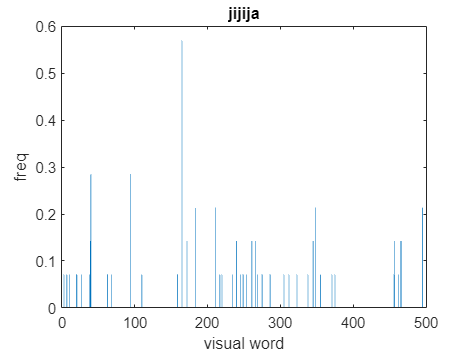



figure
bar(features)
title('jijija')
xlabel('visual word')
ylabel('freq')


categoryClassifier = trainImageCategoryClassifier(trainingSet,bag);

Training an image category classifier for 6 categories.
--------------------------------------------------------
* Category 1: A
* Category 2: B
* Category 3: C
* Category 4: D
* Category 5: G
* Category 6: H

* Encoding features for 5380 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.




confMatrix = evaluate(categoryClassifier,testSet)

Evaluating image category classifier for 6 categories.
-------------------------------------------------------

* Category 1: A
* Category 2: B
* Category 3: C
* Category 4: D
* Category 5: G
* Category 6: H

* Evaluating 12554 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                          PREDICTED
KNOWN   | A      B      C      D      G      H      
----------------------------------------------------
A       | 0.85   0.05   0.02   0.04   0.02   0.02   
B       | 0.03   0.90   0.02   0.04   0.01   0.01   
C       | 0.01   0.01   0.94   0.03   0.01   0.01   
D       | 0.01   0.01   0.04   0.93   0.01   0.01   
G       | 0.01   0.01   0.01   0.00   0.90   0.06   
H       | 0.01   0.01   0.01   0.01   0.02   0.94   

* Average Accuracy is 0.91.



confMatrix =     0.8481    0.0453    0.0224    0.0404    0.0234    0.0204
    0.0257    0.9005    0.0167    0.0367    0.0100    0.0105
    0.0090    0.0129    0.9376    0.0262    0.0062    0.0081
    0.0057    0.0076    0.0405    0.9329    0.0067    0.0067
    0.0133    0.0143    0.0100    0.0038    0.8995    0.0590
    0.0129    0.0119    0.0105    0.0071    0.0214    0.9362


## EXPERIMENTOS

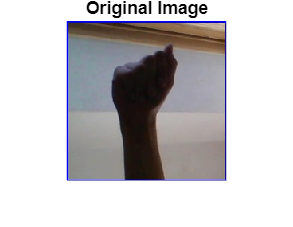



clear all
clf
close all
% Load the image (replace 'wea.jpg' with your image file path)
img = imread('C:\Users\User\Desktop\dataset\asl_alphabet_train\asl_alphabet_train\A\A1.jpg');

% Convert the image to grayscale
imgGray = rgb2gray(img);

% Apply a median filter for noise reduction (you may need to adjust the window size)

imgGray = medfilt2(imgGray, [11,11]);


% Define the size of the averaging kernel (e.g., 3x3)
kernelSize = 3;

% Create the averaging kernel
avgKernel = ones(kernelSize) / (kernelSize^2);

% Apply the average filter using imfilter
imgGray = imfilter(imgGray, avgKernel, 'conv');

% Define a laplacian filter for enhancing the image
laplacianKernel = [-1, -1, -1; -1, 9, -1; -1, -1, -1];
imgGray = imfilter(imgGray, laplacianKernel);


% threshold but adaptative
    % Specify the block size for adaptive thresholding
    blockSize = 7; % Adjust this value based on your image and requirements

    % Specify the offset value (a constant subtracted from the mean)
    offset = 5; % Adjust this value based on your image and requirements

    % Perform adaptive thresholding
    adaptiveThresholded = adaptthresh(imgGray, 'NeighborhoodSize', [blockSize, blockSize], 'ForegroundPolarity', 'bright');
    adaptiveThresholded = imbinarize(imgGray,adaptiveThresholded);

% Dilata la imagen
    % Kernel
    se = strel('disk', 7);

    % Perform dilation
    %adaptiveThresholded = imerode(adaptiveThresholded, se);
    adaptiveThresholded = imdilate(adaptiveThresholded, se);


masked2 = bsxfun(@times, img, cast(adaptiveThresholded, 'like', img));


figure;
imshow(img);
title('Original Image');

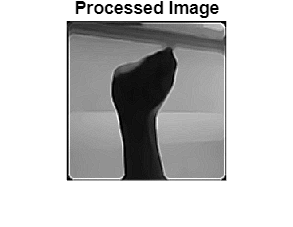


figure;
imshow(imgGray);
title('Processed Image');

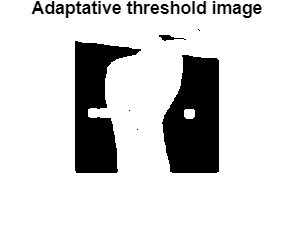



figure;
imshow(adaptiveThresholded);
title('Adaptative threshold image');

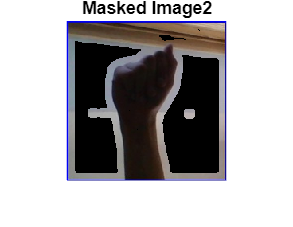



figure;
imshow(masked2);
title('Masked Image2');

## EXPERIMENTOS

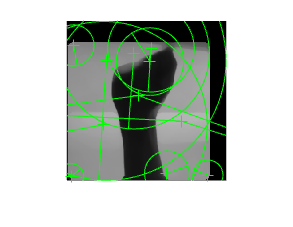


masked2 = imgGray;

points = detectSIFTFeatures(masked2);

[features,valid_points] = extractFeatures(masked2,points);


figure;
imshow(masked2);
hold on;
plot(valid_points,showOrientation=true);

## EXPERIMENTOS


% Load the image (replace 'image.jpg' with your image file path)
img = imread('C:\Users\User\Desktop\dataset\asl_alphabet_train\asl_alphabet_train\A\A1.jpg');

% Define the amount of translation in pixels (adjust as needed)
horizontalOffset = -20; % Number of pixels to move to the right
verticalOffset = 25;   % Number of pixels to move downwards

% Perform the translation to move the image to the bottom-right
translatedImage = imtranslate(img, [horizontalOffset, verticalOffset]);

translatedImage = rgb2gray(translatedImage)

outputFilePath = 'C:\Users\User\Desktop\wea2.jpg'; % Adjust the file path and format as needed

% Save the image using imwrite
imwrite(translatedImage, outputFilePath);

% Display the original and translated images
subplot(1, 2, 1);
imshow(img);
title('Original Image');

subplot(1, 2, 2);
imshow(translatedImage);
title('Translated Image (Bottom-Right)');



